alpha=[pi/2 0 pi/2 pi/2 pi/2 0];
a=[50 420 25 0 0 0];
b=[380 0 0 440 0 98];

syms teta1 teta2 teta3 teta4 teta5 teta6
teta=[teta1 teta2 teta3 teta4 teta5 teta6];
q1=Q_local(teta(1),alpha(1));
av1=a_vect_local(a(1),b(1),teta(1));
q2=Q_local(teta(2),alpha(2));
av2=a_vect_local(a(2),b(2),teta(2));
q3=Q_local(teta(3),alpha(3));
av3=a_vect_local(a(3),b(3),teta(3));
q4=Q_local(teta(4),alpha(4));
av4=a_vect_local(a(4),b(4),teta(4));
q5=Q_local(teta(5),alpha(5));
av5=a_vect_local(a(5),b(5),teta(5));
q6=Q_local(teta(6),alpha(6));
av6=a_vect_local(a(6),b(6),teta(6));

Q_total=q1*q2*q3*q4*q5*q6;
p_total=av1+q1*av2+q1*q2*av3+q1*q2*q3*av4+q1*q2*q3*q4*av5+q1*q2*q3*q4*q5*av6;

**IKP**

we have Q_total and p_total. we want to calculate $\theta_1 ,\ldotp \ldotp ,\theta_6$

miu=sin(alpha);
landa=cos(alpha);

b6_vect=b_vect(a(6),b(6),alpha(6));
c_vect=p_total-Q_total*b6_vect;

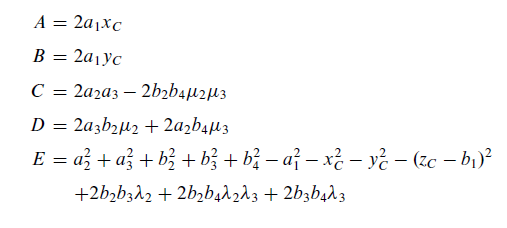

A=2.*a(1).*c_vect(1);
B=2.*a(1).*c_vect(2);
C=2.*a(2)*a(3)-2*b(2)*b(4)*miu(2)*miu(3);
D=2*a(3)*b(2)*miu(2)+2*a(2)*b(4)*miu(3);
E=a(2).^2+a(3).^2+b(2).^2+b(3).^2+b(4).^2-a(1).^2-c_vect(1).^2-c_vect(2).^2-(c_vect(3)-b(1)).^2;

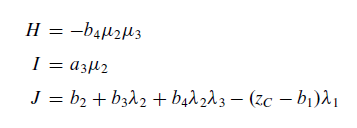

F=c_vect(2)*miu(1);
G=-c_vect(1)*miu(1);
H=-b(4)*miu(2)*miu(3);
I=a(3)*miu(2);
J=b(2)+b(3)*landa(2)+b(4)*landa(2)*landa(3)-(c_vect(3)-b(1))*landa(1);

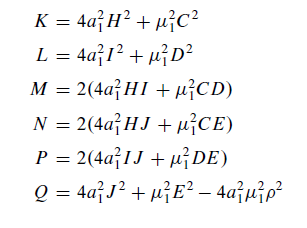

K=4*a(1).^2*H.^2 + miu(1).^2+C.^2;
L=4*a(1).^2*I.^2 + miu(1).^2+D.^2;
M=2*(4*a(1)^2*H*I+miu(1)^2*C*D);
N=2*(4*a(1)^2*H*J+miu(1)^2*C*E);
P=2*(4*a(1)^2*I*J+miu(1)^2*D*E);
Q=4*a(1)^2*J^2+miu(1)^2*E^2-4*a(1)^2*miu(1)^2*(c_vect(1)^2+c_vect(2)^2);

R = 4*a(1)^2*(J-H)^2+miu(1)^2*(E-C)^2-4*(c_vect(1)^2+c_vect(2)^2)*a(1)^2*miu(1)^2;
S = 4*(4*a(1)^2*I*(J-H)+miu(1)^2*D*(E-C));
T = 2*(4*a(1)^2*(J^2-H^2+2*I^2)+miu(1)^2*(E^2-C^2+2*D^2)-4*(c_vect(1)^2+c_vect(2)^2)*a(1)^2*miu(1)^2);
U = 4*(4*a(1)^2*I*(J+H)+miu(1)^2*D*(C+E));
V = 4*a(1)^2*(J+H)^2+miu(1)^2*(C+E)^2-4*(c_vect(1)^2+c_vect(2)^2)*a(1)^2*miu(1)^2;
coefvct = [R  S  T  U V];
syms x
eq=R*x^4+S*x^3+T*x^2+U*x+V==0;
sol = solve(eq,[x])
%theta_3 = 2*tan(sol)

function [q] = Q_local(teta, alpha)
    q = [[cos(teta) -cos(alpha).*sin(teta) sin(alpha).*sin(teta)]
        [sin(teta) cos(alpha).*cos(teta) -sin(alpha).*cos(teta)]
        [0 sin(alpha) cos(alpha)]];
end

function [av] = a_vect_local(a, b, teta)
        av = [[a.*cos(teta)]
              [a.*sin(teta)]
              [b]];
end

function [bv] = b_vect(a, b, teta)
        bv = [[a]
              [b.*sin(teta)]
              [b.*cos(teta)]];
end
